close all;
clear variables;

breath = importdata("data\breath.txt");
breathRaw = breath.data;

air = importdata("data\air.txt");
airRaw = air.data;

tt = importdata("data\TotalTime.txt");
tt = tt.data;

fr = importdata("data\samplingFrequency.txt");
fr = fr.data;

T = importdata("data\temperature.txt");
T = T.data + 273;

w_h2o = importdata("data\volumeFractionWater.txt");
w_h2o = w_h2o.data;

%Нормировка

windowSize = 5;
b = (1/windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
fr = 1/fr;
time = (0:fr:tt)';
time = time(start:end);

cAir = polyfit(time, airFiltered(:, 1), 3);
cBreath = polyfit(time, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, time);
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, time);
breathNorm = breath ./ max(breath);

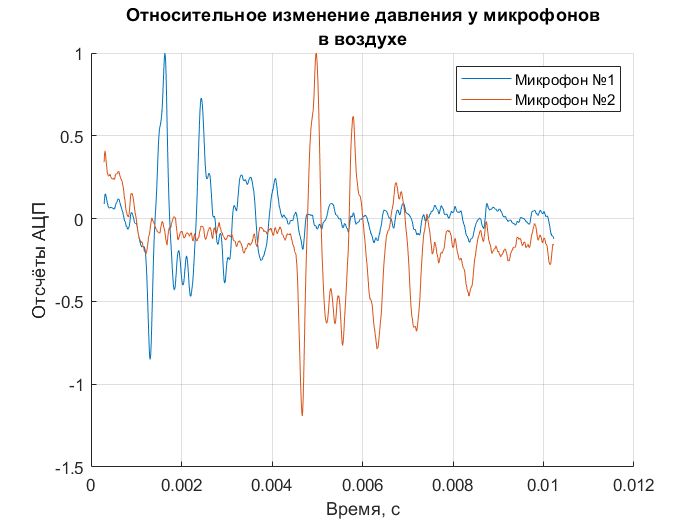

% air

zNames = {'Микрофон №1'; 'Микрофон №2'};

airF = figure();
hold on;

for i = 1:2
    plot(time, airNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(airF, "graph_air.png");  %изменена ссылка

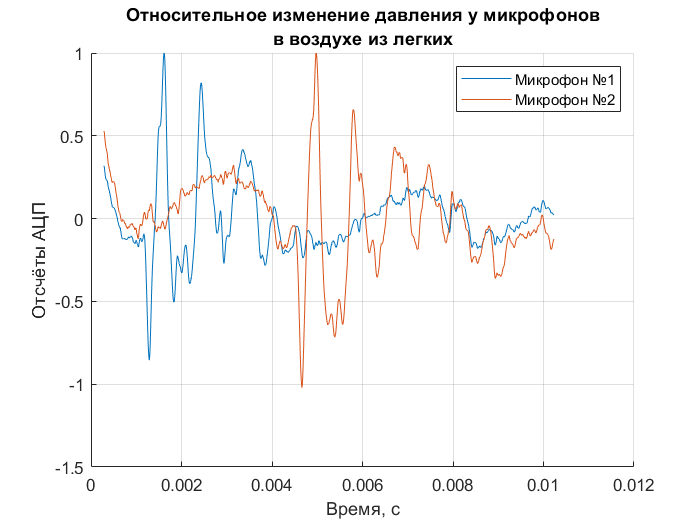

% breath

zNames = {'Микрофон №1'; 'Микрофон №2'};

breathF = figure();
hold on;

for i = 1:2
    plot(time, breathNorm(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из легких'});
xlabel('Время, с');
ylabel('Отсчёты АЦП');

legend('Location', 'NorthEast');
saveas(breathF, "graph_breath.png");  %изменена ссылка

% experimental speed without CO2

P = airNorm(1, 1);
T1 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 1)>P
        P = airNorm(i, 1);
        T1 = time(i);
    end
end

P = airNorm(1, 2);
T2 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 2)>P
        P = airNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithoutCO2_max = T2 -T1;

P = airNorm(1, 1);
T1 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 1)<P
        P = airNorm(i, 1);
        T1 = time(i);
    end
end

P = airNorm(1, 2);
T2 = time(1);
for i = 2:length(airNorm)
    if airNorm(i, 2)<P
        P = airNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithoutCO2_min = T2 -T1;

speedWithoutCO2 = (2*1.158)/(TimeWithoutCO2_max + TimeWithoutCO2_min);  % расстояние / среднее время между пиками [м/с]

% experimental speed with CO2

P = breathNorm(1, 1);
T1 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 1)>P
        P = breathNorm(i, 1);
        T1 = time(i);
    end
end

P = breathNorm(1, 2);
T2 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 2)>P
        P = breathNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithCO2_max = T2 -T1;

P = breathNorm(1, 1);
T1 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 1)<P
        P = breathNorm(i, 1);
        T1 = time(i);
    end
end

P = breathNorm(1, 2);
T2 = time(1);
for i = 2:length(breathNorm)
    if breathNorm(i, 2)<P
        P = breathNorm(i, 2);
        T2 = time(i);
    end
end

TimeWithCO2_min = T2 -T1;

speedWithCO2 = (2*1.158)/(TimeWithCO2_max + TimeWithCO2_min);  % расстояние / среднее время между пиками [м/с]

% рассчёт концентрации Н2О

CP = [1.0036; 1.863; 0.838];  % вносим константы
CN = [0.7166; 1.403; 0.649];
m = [28.97; 18.01; 44.01];
T = 295.4;
R = 8314;

k = 0;
X = [1-0.0003-k/1000; k/1000; 0.0003];

sum_CP = 0;
sum_CN = 0;
sum_m = 0;
for i = 1:3
    sum_CP = sum_CP + (m(i)*CP(i)*X(i));
    sum_CN = sum_CN + (m(i)*CN(i)*X(i));
    sum_m = sum_m + (m(i)*X(i));
end
g = sum_CP/sum_CN;
U = sqrt((g*R*T)/sum_m);

while U<speedWithoutCO2
    k = k+1;
    X = [1-0.0003-k/1000; k/1000; 0.0003];

    sum_CP = 0;
    sum_CN = 0;
    sum_m = 0;
    for i = 1:3
        sum_CP = sum_CP + (m(i)*CP(i)*X(i));
        sum_CN = sum_CN + (m(i)*CN(i)*X(i));
        sum_m = sum_m + (m(i)*X(i));
    end
    g = sum_CP/sum_CN;
    U = sqrt((g*R*T)/sum_m);
end

%теоретический расчет скорости звука в воздухе

T = 295.4;
R = 8314;
w = [0.9817, w_h2o, 0.0003];
m = [28.97, 18.01, 44.01];
Cp = [1.0036, 1.863, 0.838];
Cv = [0.7166, 1.403, 0.649];

Cv_0 = 0;
for i = 1:3
    Cv_0 = Cv_0 + m(i) * Cv(i) * w(i);
end

Cp_0 = 0;
for i = 1:3
    Cp_0 = Cp_0 + m(i) * Cp(i) * w(i);
end

m_0 = 0;
for i = 1:3
    m_0 = m_0 + m(i) * w(i);
end

u1 = sqrt((Cp_0 * R * T)/(Cv_0 * m_0));

% зависимость скорости звука от концентрации CO2
w_CO2 = linspace(0, 0.02, 50);

u = zeros(1, 50);

for k = 1:50
    w(1, 1) = 1 - w(1, 2) - w_CO2(1, k);
    w(1, 3) = w_CO2(1, k);
    Cv_0 = 0;
    for i = 1:3
        Cv_0 = Cv_0 + m(i) * Cv(i) * w(i);
    end
    
    Cp_0 = 0;
    for i = 1:3
        Cp_0 = Cp_0 + m(i) * Cp(i) * w(i);
    end

    m_0 = 0;
    for i = 1:3
        m_0 = m_0 + m(i) * w(i);
    end

    u(k) = sqrt((Cp_0 * R * T)/(Cv_0 * m_0));
end

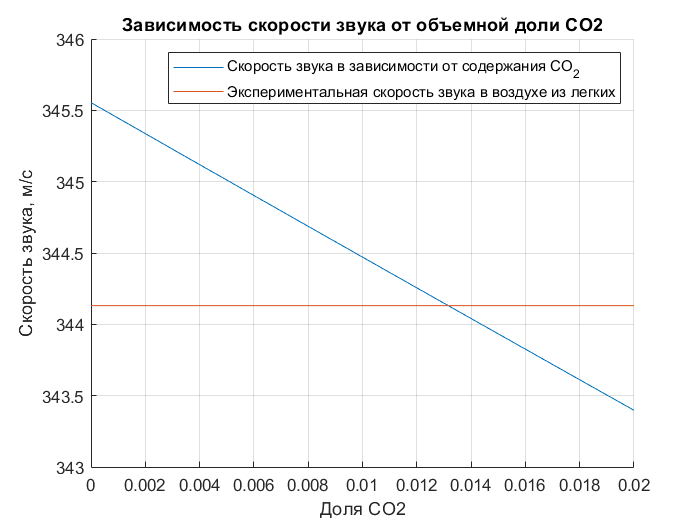

% график
lineF = figure();
hold on;

plot(w_CO2(1, :), u(1, :));
u_exp = ones(1, 50)*speedWithCO2;
plot(w_CO2(1, :), u_exp(1, :));


grid on;
title({'Зависимость скорости звука от объемной доли CO2'});
xlabel('Доля CO2');
ylabel('Скорость звука, м/с');

legend('Скорость звука в зависимости от содержания CO_2', 'Экспериментальная скорость звука в воздухе из легких', 'Location', 'NorthEast');

%saveas(lineF, "result.png");

% рассчёт концентрации СО2

X_H20 = X(2);
k = 0;
X = [1-X_H20-k/1000; X_H20; k/1000];

sum_CP = 0;
sum_CN = 0;
sum_m = 0;
for i = 1:3
    sum_CP = sum_CP + (m(i)*CP(i)*X(i));
    sum_CN = sum_CN + (m(i)*CN(i)*X(i));
    sum_m = sum_m + (m(i)*X(i));
end
U2 = (sum_CP*R*T)/(sum_m*sum_CN);

while U2>speedWithCO2*speedWithCO2
    k = k+1;
    X = [1-X_H20-k/1000; X_H20; k/1000];

    sum_CP = 0;
    sum_CN = 0;
    sum_m = 0;
    for i = 1:3
        sum_CP = sum_CP + (m(i)*CP(i)*X(i));
        sum_CN = sum_CN + (m(i)*CN(i)*X(i));
        sum_m = sum_m + (m(i)*X(i));
    end
    U2 = (sum_CP*R*T)/(sum_m*sum_CN);
end
